## Задание 1

function plotPoleZeroMaps(sys, name)
    % Проверка, что входная система является объектом tf
    if ~isa(sys, 'tf')
        error('Входная система должна быть объектом tf.');
    end

    % Построение карты нулей и полюсов для разомкнутой системы
    figure('Position', [0 0 800 500]);

    subplot(1, 2, 1); % Разделение фигуры на два графика
    pzmap(sys);
    % grid on;
    title('Нули и полюса разомкнутой системы');
    xlabel('Re');
    ylabel('Im');
    
    % Создание замкнутой системы с обратной связью
    sys_closed = feedback(sys, 1);

    % Построение карты нулей и полюсов для замкнутой системы
    subplot(1, 2, 2);
    pzmap(sys_closed);
    % grid on;
    title('Нули и полюса замкнутой системы');
    xlabel('Re');
    ylabel('Im');

    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotStepResponses(sys, name)
    %   График переходных характеристик для разомкнутой и замкнутой систем.

    if ~isa(sys, 'tf')
        error('Входная система должна быть объектом tf.');
    end

    % Создаем фигуру для отображения
    figure('Position', [100, 100, 1200, 500]); % Широкая фигура для сравнения

    % Переходная характеристика разомкнутой системы
    subplot(1, 2, 1);
    step(sys);
    %plot(t_open, y_open, 'b', 'LineWidth', 2);
    grid on;
    xlabel('Time (s)');
    ylabel('Amplitude');
    title({"Переходная характеристика", "разомкнутой системы"});

    % Переходная характеристика замкнутой системы
    sys_closed = feedback(sys, 1);
    subplot(1, 2, 2);
    step(sys_closed);
    %plot(t_closed, y_closed, 'r', 'LineWidth', 2);
    grid on;
    xlabel('Time (s)');
    ylabel('Amplitude');
    title({"Переходная характеристика", "замкнутой системы"});

    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotNyquist(sys, name)
    figure('Position', [100, 100, 1000, 800]);
    w = 0:0.01:30000;
    nyquist(sys, w);
    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function plotBode(sys, name)
    % Создание фигуры
    figure('Position', [0 0 800 600]);
    
    % Получение данных для Bode-графика
    [mag, phase, w] = bode(sys);
    mag = squeeze(20*log10(mag)); % Преобразуем в dB
    phase = squeeze(phase);      % Преобразуем в градусы
    
    % Построение графика амплитуды
    subplot(2, 1, 1);
    hold on;

    % Закрашиваем область, где амплитуда больше 0 дБ
    valid_indices = mag > 0;  % Logical indices where mag > 0
    w_filtered = w(valid_indices);  % Filtered w
    mag_filtered = mag(valid_indices);  % Filtered mag
    % Ensure the data is closed for fill (return to baseline)
    w_fill = [w_filtered; flipud(w_filtered)];  % Duplicate and reverse for closure
    mag_fill = [mag_filtered; zeros(size(mag_filtered))];  % Close to baseline

    fill_area = fill(w_fill, mag_fill, 'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');

    bode_line_mag = plot(w, mag, 'b', 'LineWidth', 1.5); % Амплитудный график
    grid on;
    set(gca, 'XScale', 'log'); % Логарифмическая ось частот
    xlabel('Frequency (rad/s)');
    ylabel('Magnitude (dB)');
    title('Bode Magnitude Plot');
    ylim([min(mag) - 10, max(mag) + 10]); % Настройка диапазона амплитуды
    legend([fill_area, bode_line_mag], {'Magnitude > 0 dB', 'Magnitude'}, 'Location', 'best');
    
    % Построение графика фазы
    subplot(2, 1, 2);
    hold on;
    bode_line_phase = plot(w, phase, 'b', 'LineWidth', 1.5); % Фазовый график
    
    % Рисуем линии на фазовом графике
    k_max = 3; % Максимальное значение k
    phase_lines = [];
    for k = 0:k_max
        phi_plus = (2*k+1)*180;   % +pi в градусах
        phi_minus = -(2*k+1)*180; % -pi в градусах
        line_plus = yline(phi_plus, '--r', 'LineWidth', 1);
        line_minus = yline(phi_minus, '--r', 'LineWidth', 1);
        phase_lines = [phase_lines, line_plus, line_minus]; %#ok<AGROW>
    end
    
    % Поиск частот, где амплитуда пересекает 0 дБ
    zero_crossings = find(diff(sign(mag)) ~= 0);
    vertical_lines = [];
    for idx = zero_crossings'
        v_line = xline(w(idx), '--k', 'LineWidth', 1.5);
        vertical_lines = [vertical_lines, v_line]; %#ok<AGROW>
    end
    
    grid on;
    set(gca, 'XScale', 'log'); % Логарифмическая ось частот
    xlabel('Frequency (rad/s)');
    ylabel('Phase (deg)');
    title('Bode Phase Plot');
    ylim([min(phase) - 30, max(phase) + 30]); % Настройка диапазона фазы
    
    % Легенда
    legend([bode_line_phase, phase_lines(1), vertical_lines], ...
        {'Phase', '\phi = \pm(2k+1)\pi', 'Amplitude = 0 dB'}, ...
        'Location', 'best');
    
    % Экспорт графика
    exportgraphics(gcf, 'figs/' + name + '.png', 'Resolution', 300);
end

function doTask1(num, den, name)
    open_sys = tf(num, den);
    close_sys = feedback(open_sys, 1);
    ans = "Разомкнутая система"
    pole(open_sys)
    ans = "Замкнутая система"
    pole(close_sys)
    plotNyquist(open_sys, "task_1_" + name + "_nyquist");
    plotPoleZeroMaps(open_sys, "task_1_" + name + "_zeros_poles");
    plotStepResponses(open_sys, "task_1_" + name + "_step");
    plotBode(open_sys, "task_1_" + name + "_bode");
end

### Объект 1

ans = "Разомкнутая система"

ans =    3.0000 + 0.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i


ans = "Замкнутая система"

ans =  -92.8151 + 0.0000i
  -1.3498 + 0.0000i
  -0.1663 + 1.1765i
  -0.1663 - 1.1765i
   0.4975 + 0.0000i


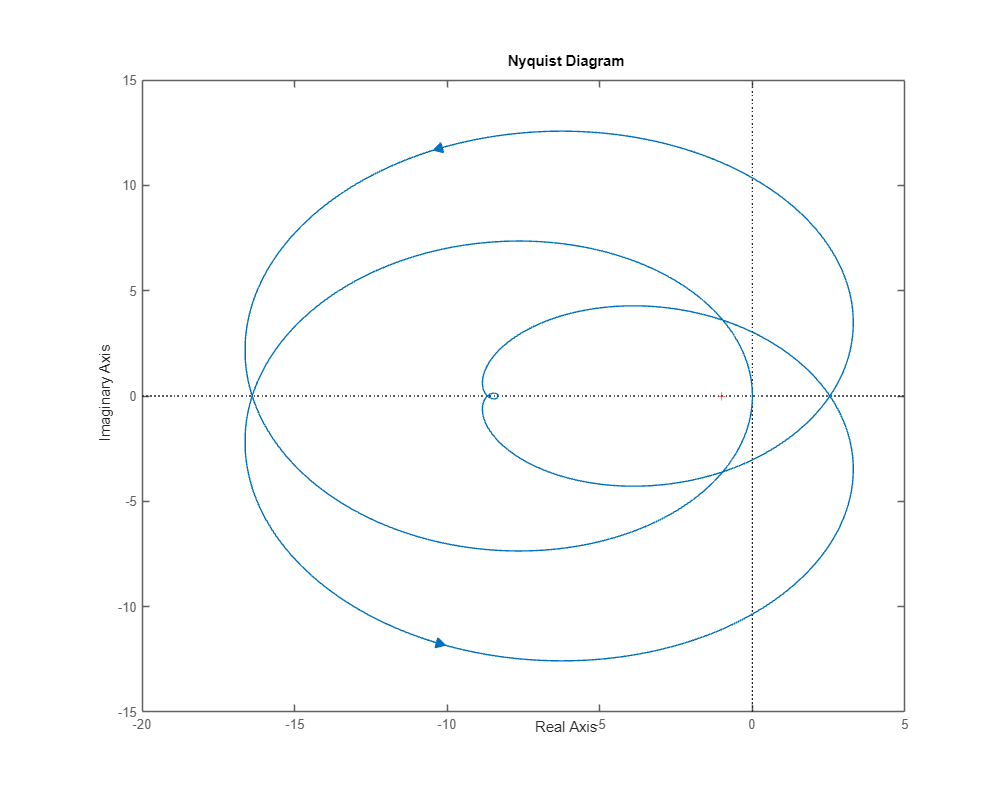

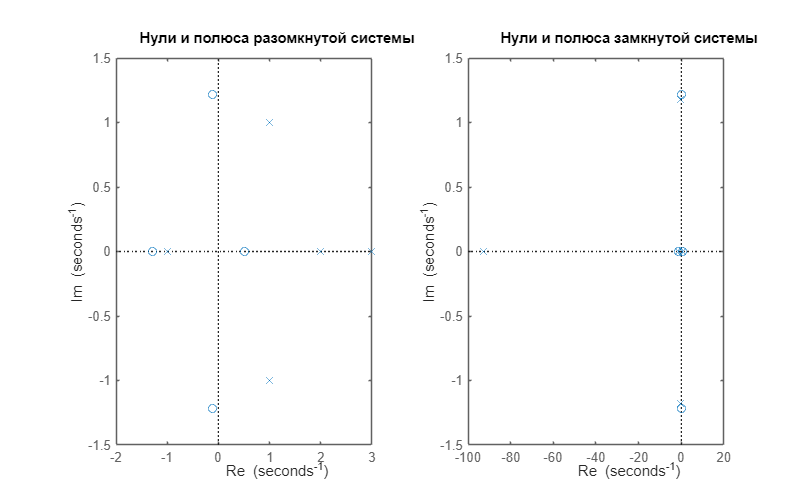

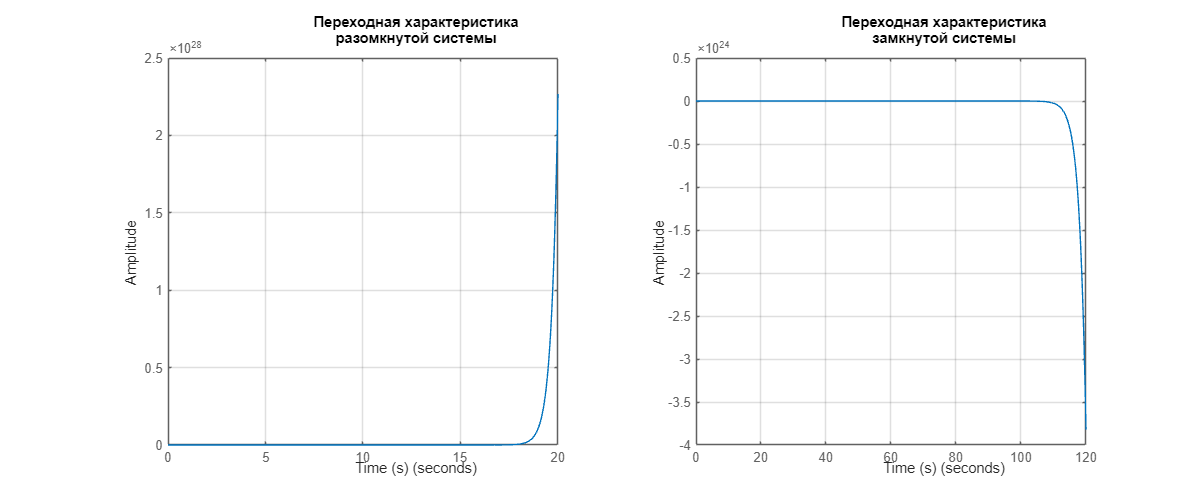

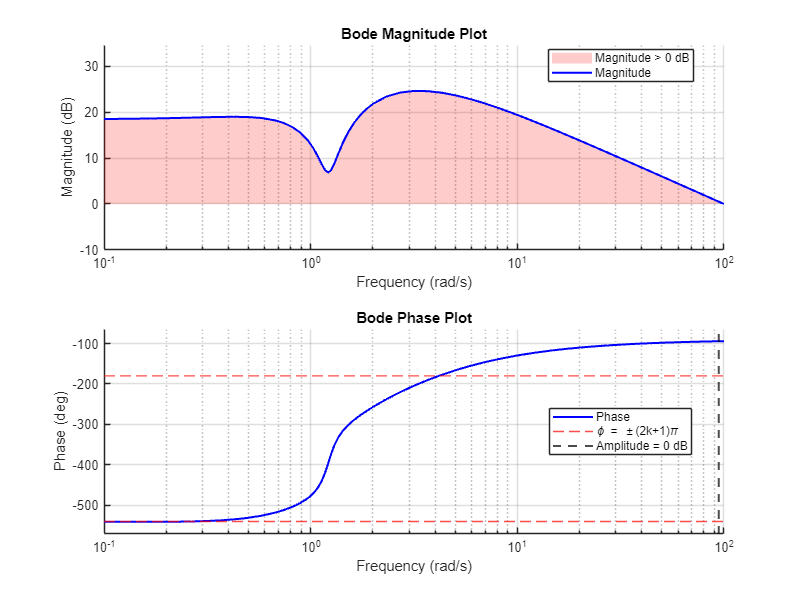

doTask1([100, 100, 100, 100, -100], [1, -6, 11, -4, -10, 12], "obj_1")

### Объект 2

ans = "Разомкнутая система"

ans =   -8.1009 + 0.0000i
  -1.1890 + 4.4248i
  -1.1890 - 4.4248i
  -0.2606 + 0.4630i
  -0.2606 - 0.4630i


ans = "Замкнутая система"

ans =   -8.0765 + 0.0000i
  -1.1348 + 4.4632i
  -1.1348 - 4.4632i
  -0.9676 + 0.0000i
   0.3137 + 0.0000i


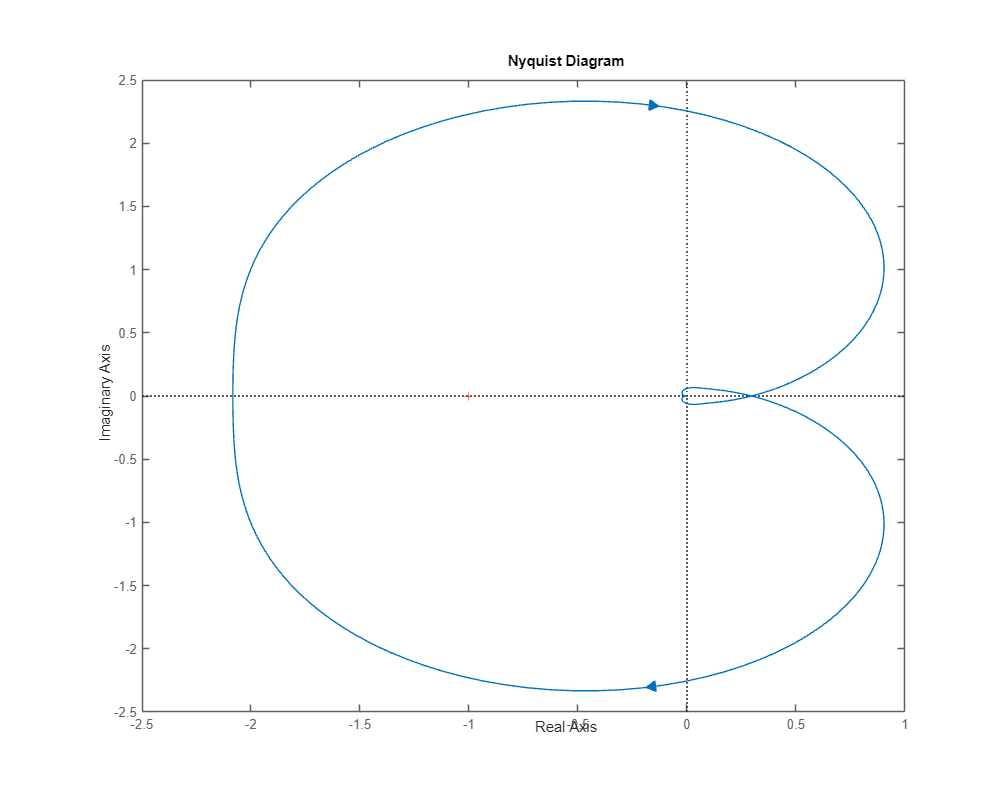

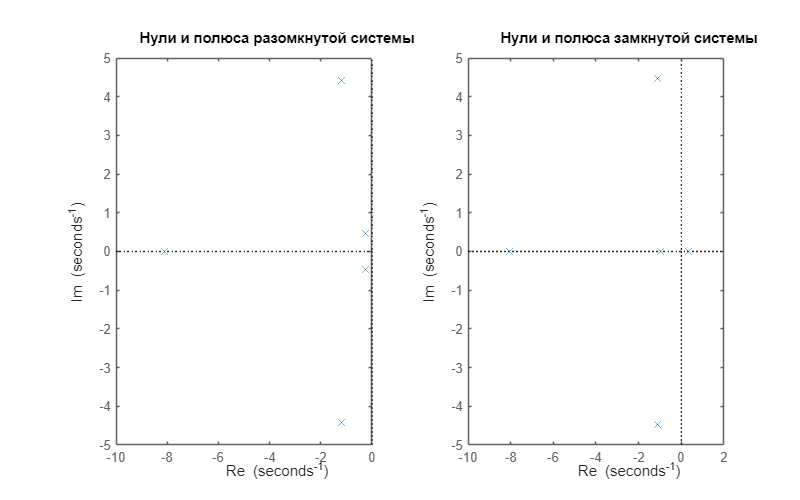

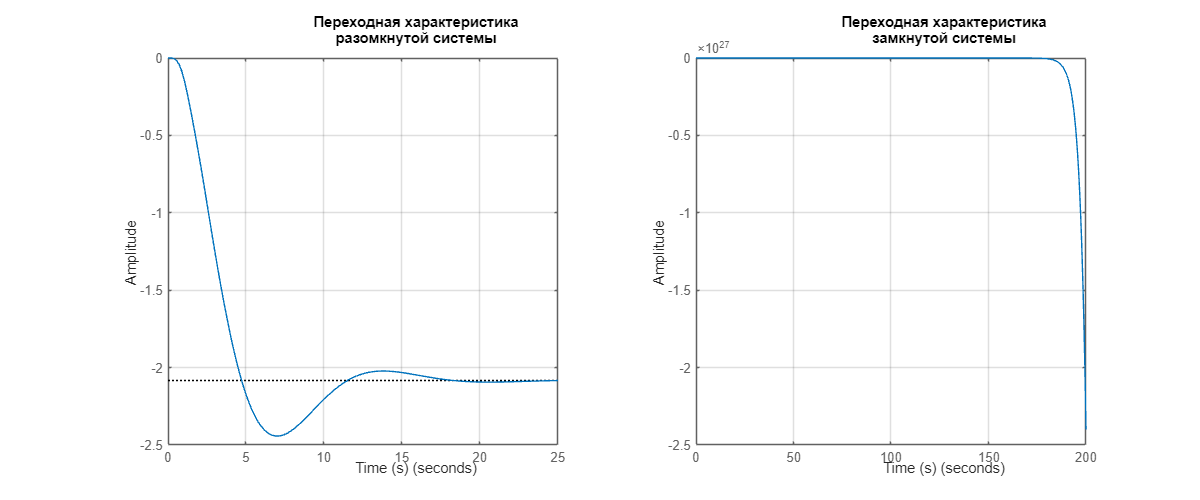

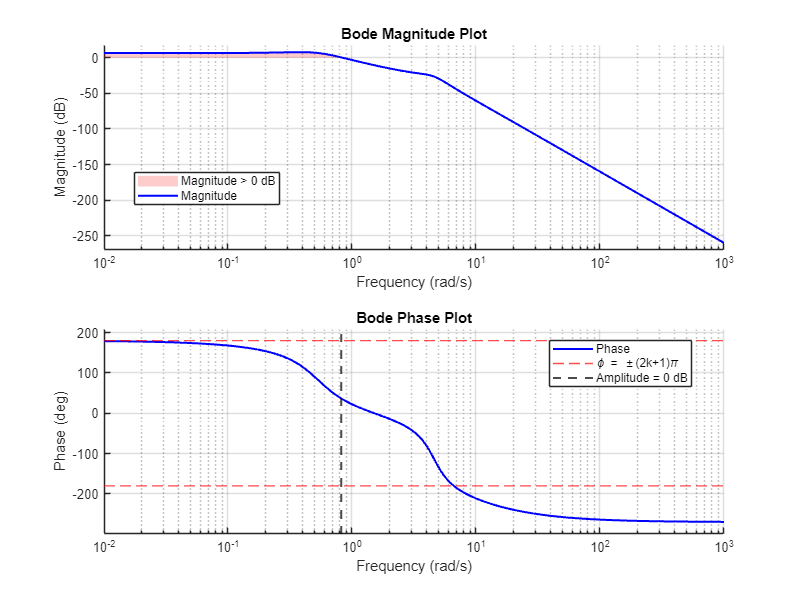

doTask1([-100], [1, 11, 46, 194, 100, 48], "obj_2")

### Объект 3

poly([-10, -1, -10, 0, -10])

ans =            1          31         330        1300        1000           0


ans = "Разомкнутая система"

ans =    3.0000 + 0.0000i
  -1.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 1.0000i
   1.0000 - 1.0000i


ans = "Замкнутая система"

ans =   -3.8683 +10.7179i
  -3.8683 -10.7179i
  -3.7512 + 0.0000i
  -1.0000 + 0.0000i
  -0.0123 + 0.0000i


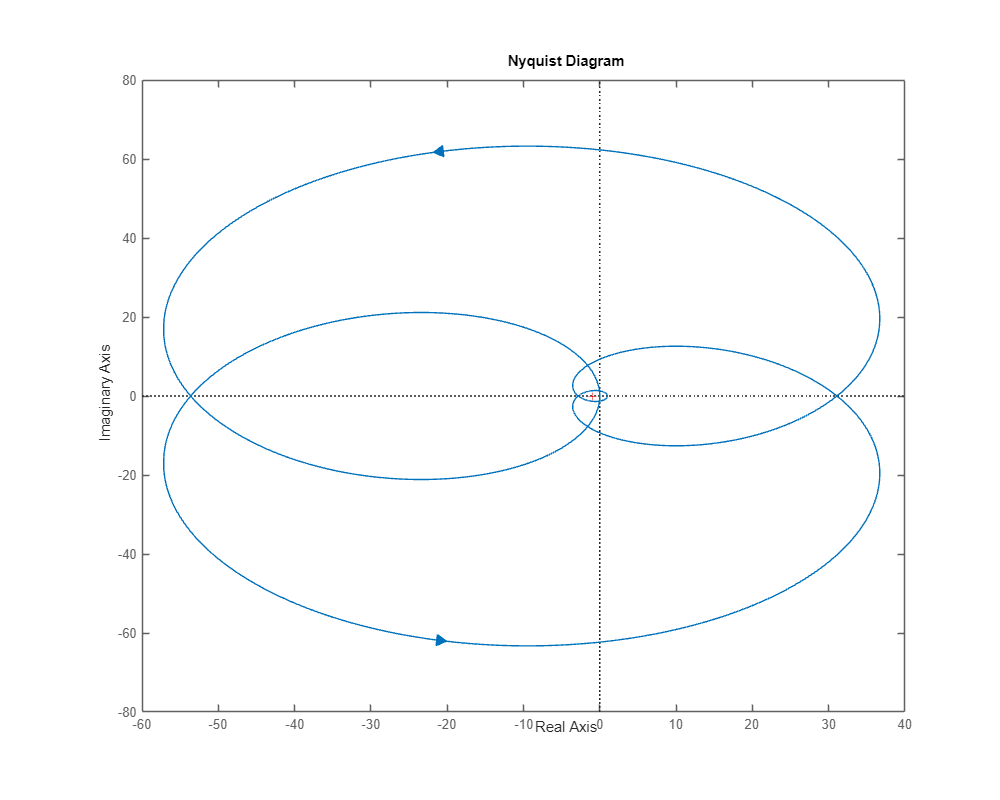

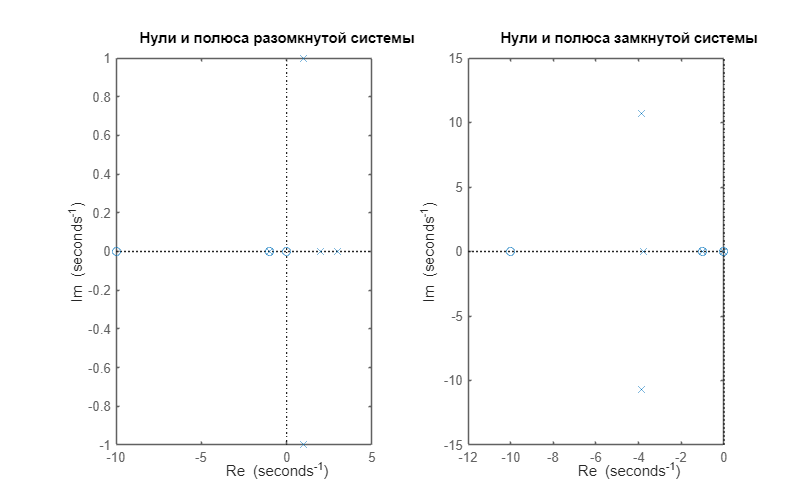

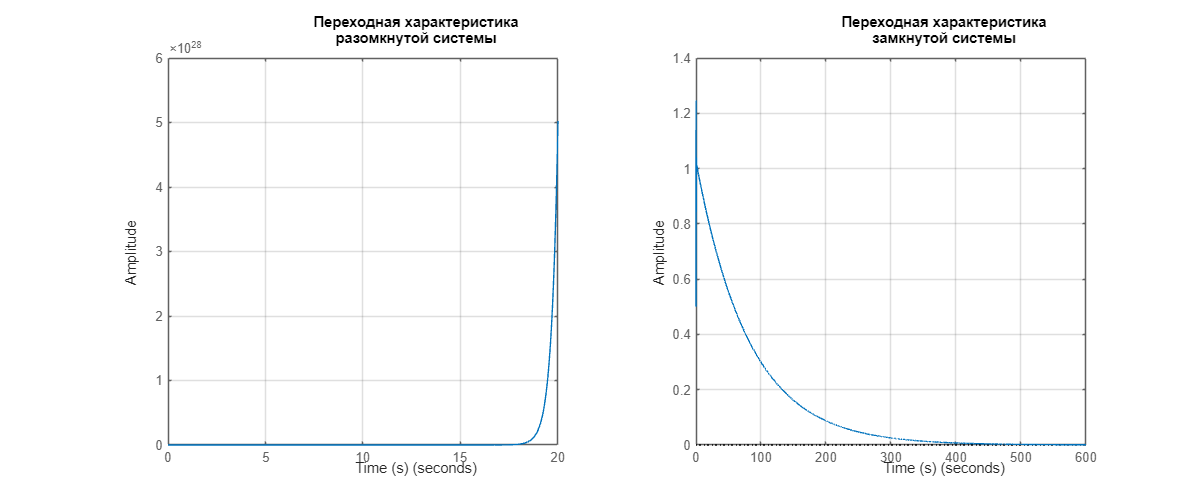

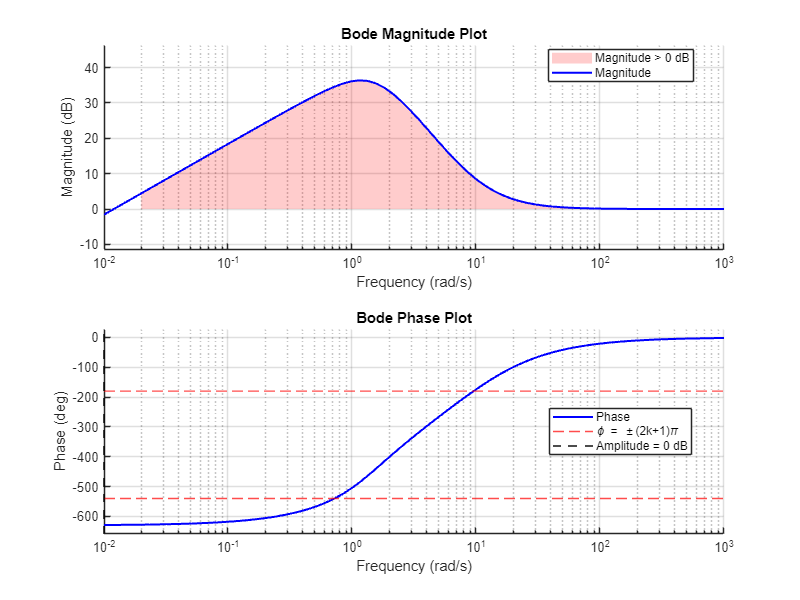

doTask1(poly([-10, -1, -10, 0, -10]), [1, -6, 11, -4, -10, 12], "obj_3")

## Задание 2

num1 = [1, -3];
den1 = [1, 2, 6];

num2 = [10, -13, 10, -2];
den2 = [10, 14, 5, 0.5];

sys1 = tf(num1, den1);
sys2 = tf(num2, den2);

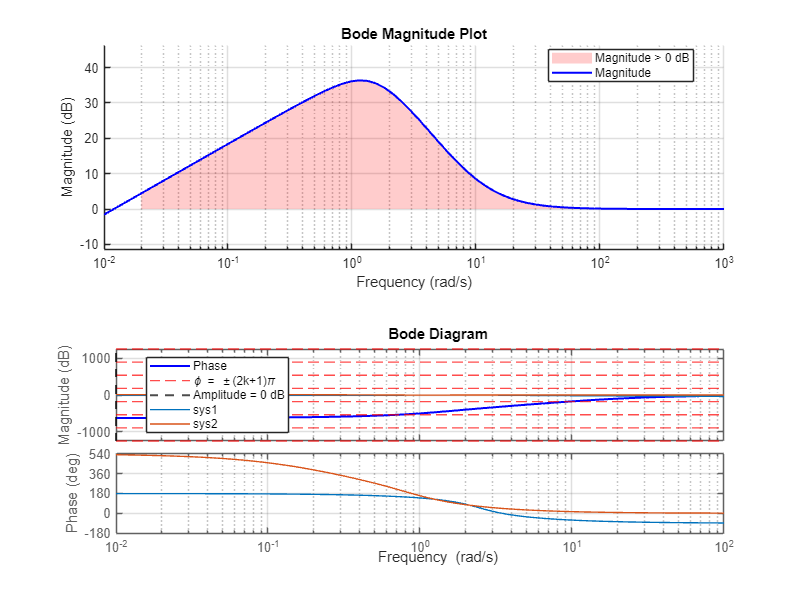

bode(sys1);
grid("on");
bode(sys2);
grid("on");

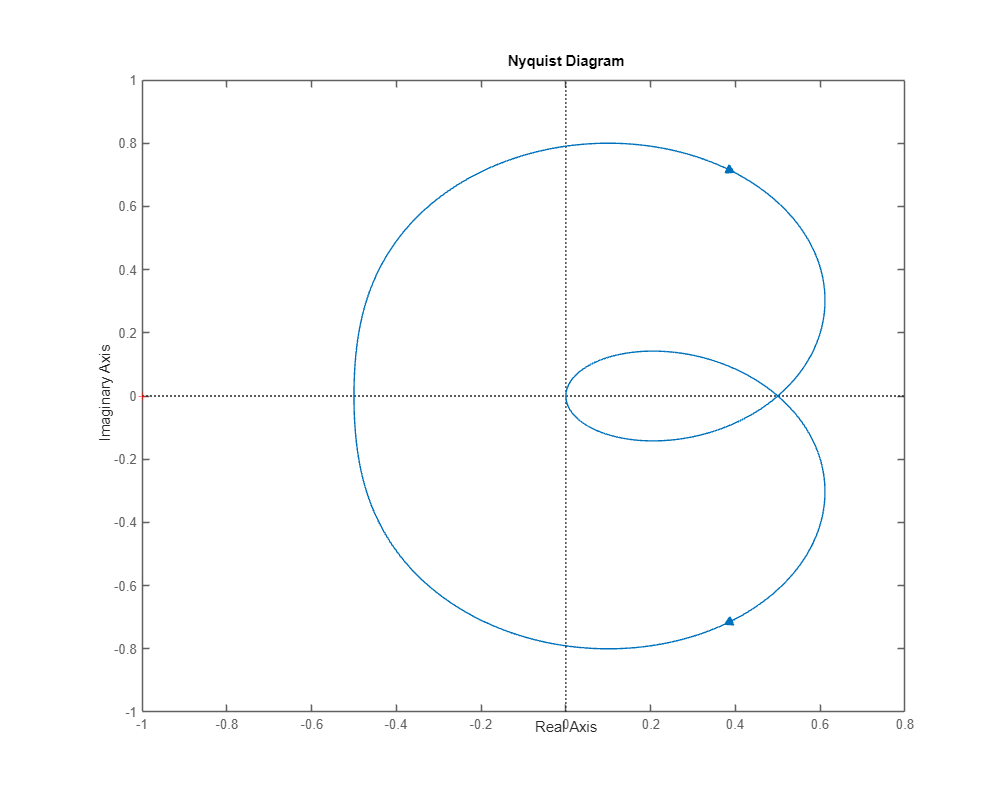

plotNyquist(sys1, "task_2_1_nyquist");

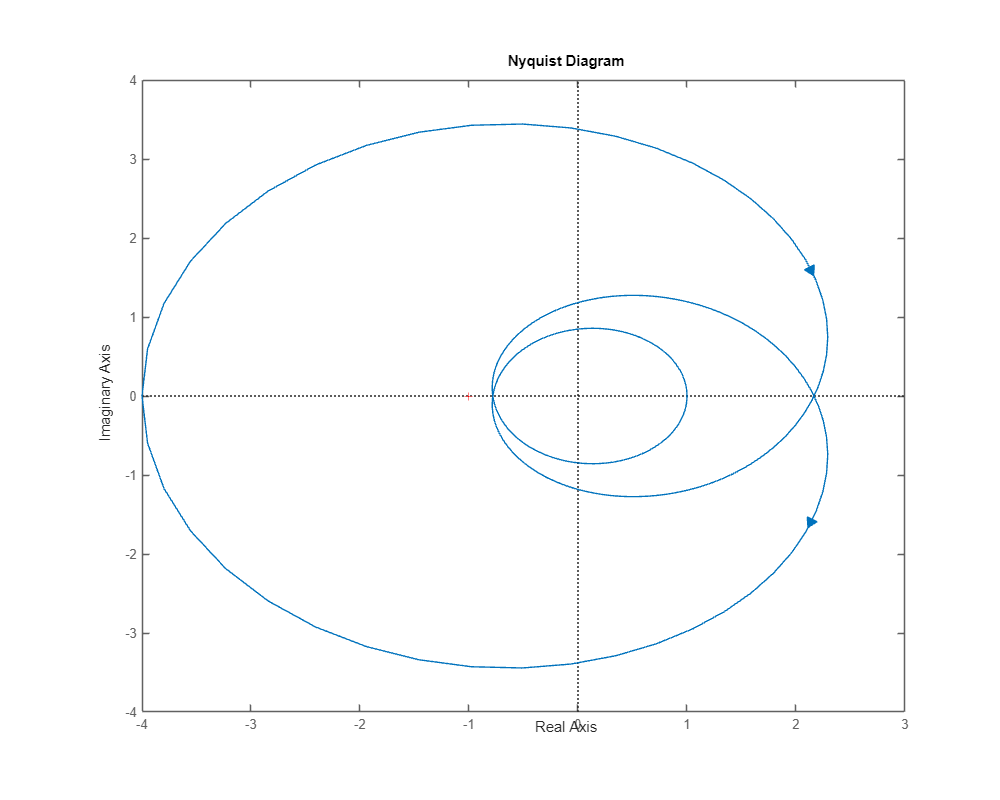

plotNyquist(sys2, "task_2_2_nyquist");

pole(sys1)

ans =   -1.0000 + 2.2361i
  -1.0000 - 2.2361i


pole(sys2)

ans =    -0.9118
   -0.3131
   -0.1752


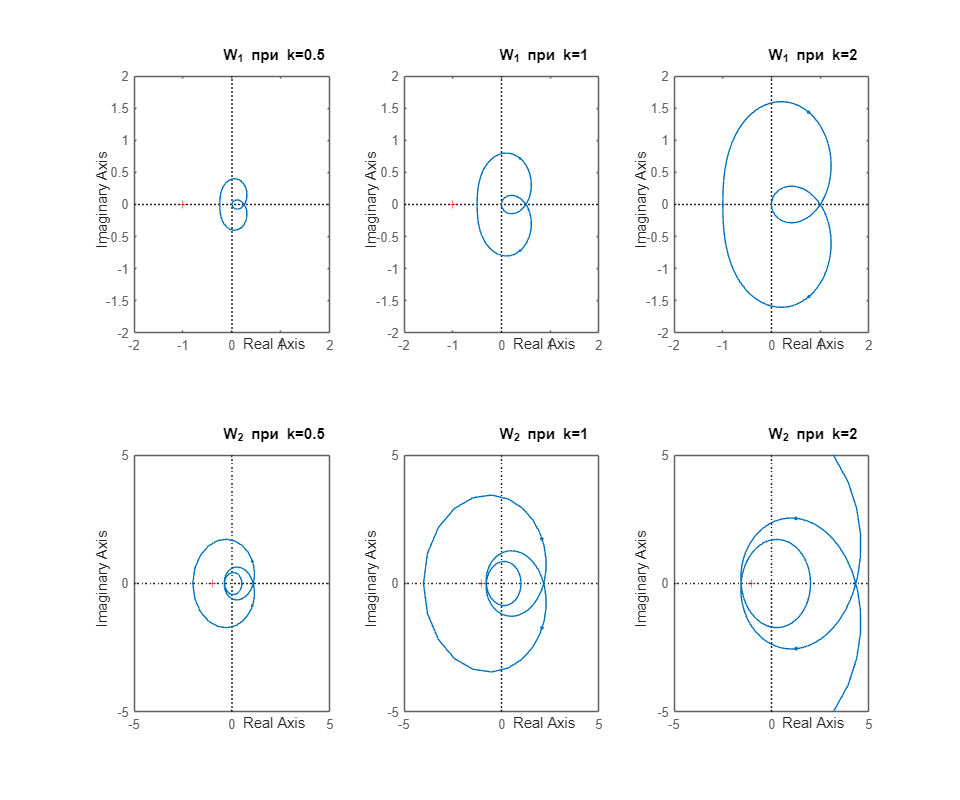

figure('Position', [100, 100, 1200, 1000]); % Широкая фигура для сравнения

k = [0.5, 1, 2];
w = 0:0.02:30000;

% Predefine limits for each row
xlim_row1 = [-2, 2]; % Adjust as needed for your system
ylim_row1 = [-2, 2];
xlim_row2 = [-5, 5];
ylim_row2 = [-5, 5];

% First row: W_1
for i = 1:3
    subplot(2, 3, i);
    sys = tf(k(i) * num1, den1);
    nyquist(sys, w);
    title("W_1 при k=" + num2str(k(i)));
    xlim(xlim_row1);
    ylim(ylim_row1);
end

% Second row: W_2
for i = 1:3
    subplot(2, 3, 3 + i);
    sys = tf(k(i) * num2, den2);
    nyquist(sys, w);
    title("W_2 при k=" + num2str(k(i)));
    xlim(xlim_row2);
    ylim(ylim_row2);
end
exportgraphics(gcf, 'figs/task_2_ks_nyaquist.png', 'Resolution', 300);

function plotClosed(num, den, ks, n, name)
    figure('Position', [100, 100, n * 500, 500]); % Широкая фигура для сравнения
    for i=1:n
        subplot(1, n, i);
        sys = tf(ks(i) * num, den);
        closed = feedback(sys, 1);
        step(closed);
        pole(closed)
        %plot(t, y, 'b', 'LineWidth', 2);
        grid on;
        title("Step Response for k=" + num2str(ks(i)));
    end
    exportgraphics(gcf, "figs/task_2_" + name + "_ksteps.png", 'Resolution', 300);
end

ans =   -1.5000 + 0.8660i
  -1.5000 - 0.8660i


ans =    -5.5414
    0.5414


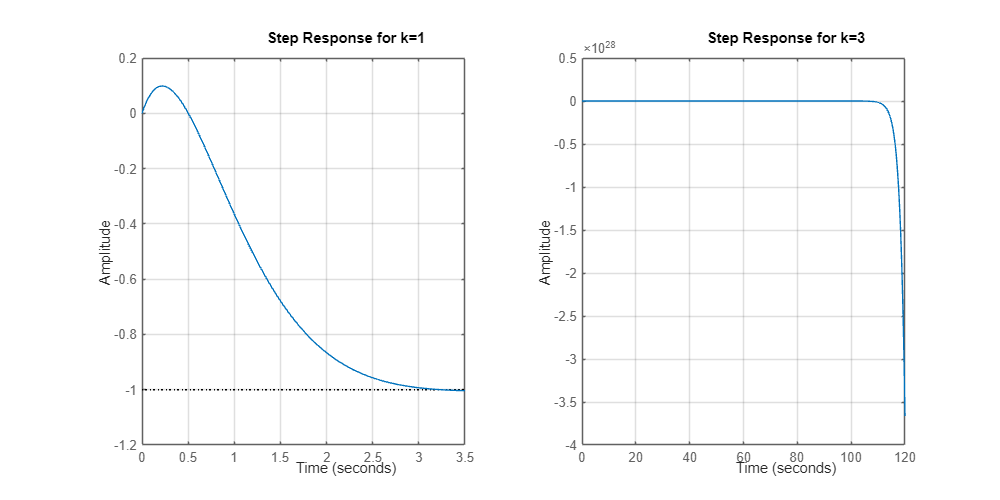

plotClosed(num1, den1, [1, 3], 2, "W1");

roots([10, -13, 10, -2])

ans =    0.5100 + 0.6740i
   0.5100 - 0.6740i
   0.2799 + 0.0000i


roots([10, 14, 5, +0.5])

ans =    -0.9118
   -0.3131
   -0.1752


[mag, phase, w] = bode(sys2);

% Find the frequency where phase equals -180 degrees
[~, idx] = min(abs(phase_deg - 180)); % Closest to -180 degrees

Unrecognized function or variable 'phase_deg'.

freq_at_180 = w(idx); % Corresponding frequency
amp_at_0 = mag

% Display the result
fprintf('The frequency at -180 degrees phase is %.4f rad/s\n', freq_at_180);

ans =   -0.5491 + 0.4267i
  -0.5491 - 0.4267i
  -0.0564 + 0.0000i


ans =   -0.3946 + 0.6851i
  -0.3946 - 0.6851i
   0.0123 + 0.0000i


ans =    0.0265 + 0.8857i
   0.0265 - 0.8857i
   0.1220 + 0.0000i


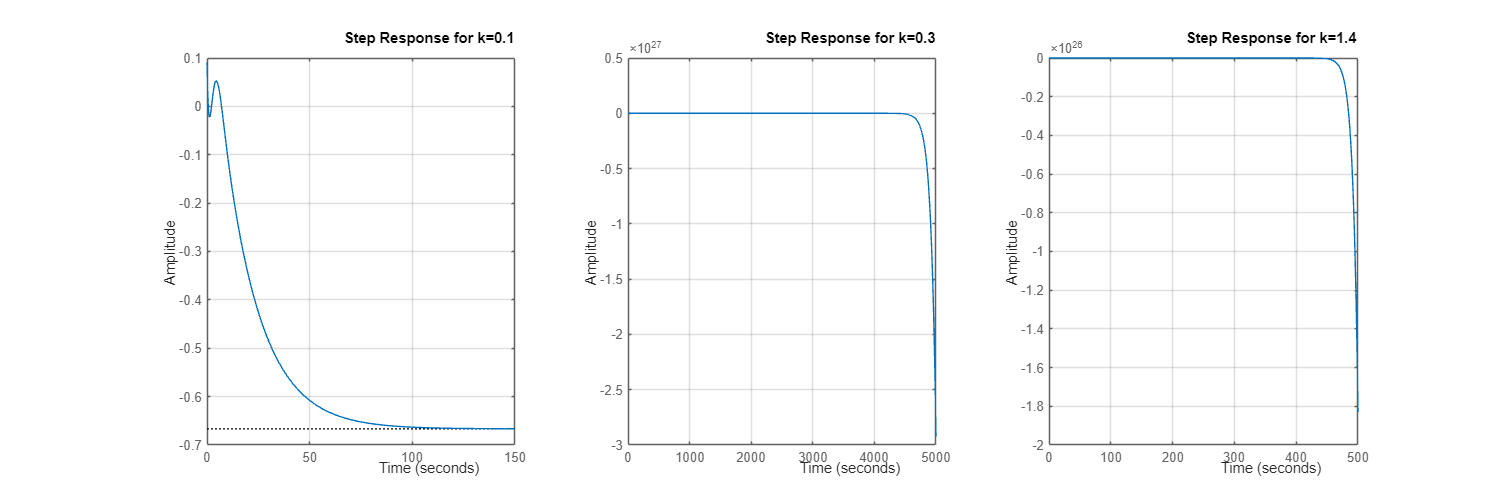

plotClosed(num2, den2, [0.1, 0.3, 1.4], 3, "W2");

## Задание 3

% Заданные передаточные функции
W3 = tf([7, 5], [1, 4, 0]);
W4 = tf([20, 1.6, 2], [10, -10, -0.1, 0.1]);

% Функция для добавления чистого запаздывания
addDelay = @(sys, tau) sys * tf([1], [1], 'InputDelay', tau);

pole(W3)
pole(W4)

% Значения коэффициента запаздывания
tau_values = [0.3053, 0.5930, 15.3138]; % Пример значений для анализа

figure('Position', [100, 100, 1200, 1000]); % Широкая фигура для сравнения

w = 0:0.02:30000;

% Predefine limits for each row
xlim_row1 = [-2, 2]; % Adjust as needed for your system
ylim_row1 = [-2, 2];
xlim_row2 = [-2, 2];
ylim_row2 = [-2, 2];

% First row: W_1
for i = 1:length(tau_values)
    subplot(2, 3, i);
    sys = addDelay(W3, tau_values(i));
    pole(feedback(sys, 1))
    nyquist(sys, w);
    title("W_3 при \tau = " + num2str(tau_values(i)));
    xlim(xlim_row1);
    ylim(ylim_row1);
end

% Second row: W_2
for i = 1:length(tau_values)
    subplot(2, 3, 3 + i);
    sys = addDelay(W4, tau_values(i));
    pole(feedback(sys, 1))
    nyquist(sys, w);
    title("W_4 при \tau = " + num2str(tau_values(i)));
    xlim(xlim_row2);
    ylim(ylim_row2);
end
%exportgraphics(gcf, 'figs/task_3_taus_nyaquist.png', 'Resolution', 300);

figure();
bode(W4);
grid();

figure();
bode(addDelay(W4, 1));
grid();

function doTask3(sys, taus, n, name)
    figure('Position', [100, 100, n * 300, 300]); % Широкая фигура для сравнения
    addDelay = @(sys, tau) sys * tf([1], [1], 'InputDelay', tau);
    for i=1:n
        subplot(1, n, i);
        sys_delayed = addDelay(sys, taus(i));
        closed = feedback(sys_delayed, 1);
        pole(closed)
        step(closed);
        %plot(t, y, 'b', 'LineWidth', 2);
        grid on;
        title("SR for \tau = " + num2str(taus(i)));
        %xlim([0, 50]);
    end
    exportgraphics(gcf, "figs/task_3_" + name + "_tausteps.png", 'Resolution', 300);
end

doTask3(W3, [0, 0.3, 0.4], 3, "W3");

doTask3(W4, [1.6, 1.8], 2, "W4_2");